clear; close all;

f0 = 1e3;
fs = 40*f0;
dt = 1/fs;
t  = 0:dt:6/f0-dt;
N  = length(t);
s  = 2*cos(2*pi*f0*t);

r = randi(round(length(t)/4))

r = 46

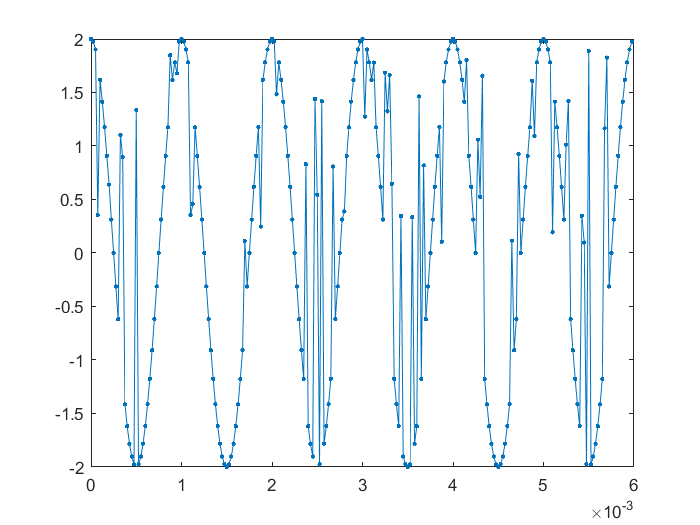

r = randperm(length(t),r);
s(r) = 2*rand(size(r));

plot(t,s,'.-');

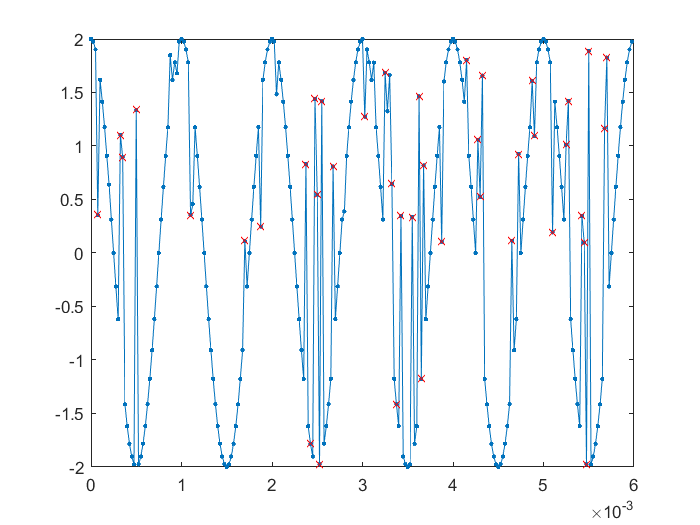


G = zeros(1,N);
for i = 3:length(s)-2
    if ((abs(s(i)-s(i-1))>0.35)&&(abs(s(i)-s(i+1))>0.35))||...
            ((abs(s(i)-s(i-2))>0.7)&&(abs(s(i)-s(i+2))>0.7))
        G(i) = i;
    end
end
G(G==0) = [];
plot(t,s,'.-'); hold on;
plot(t(G),s(G),'xr','LineStyle','none'); hold off;

disp(length(G));

    41



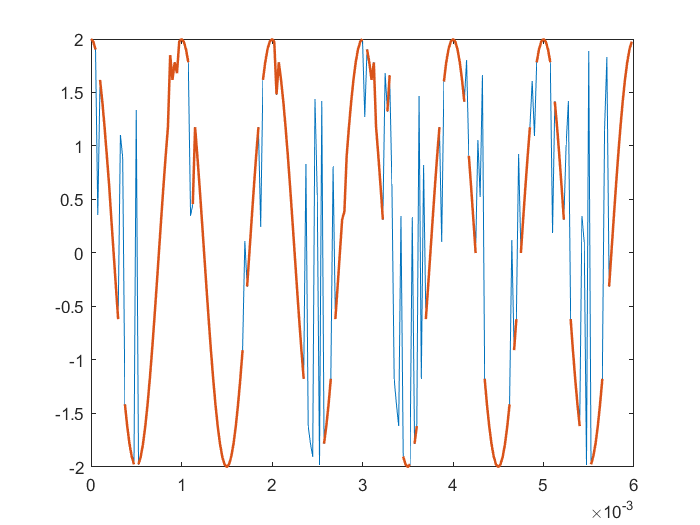


t1 = t;
t1(G) = NaN;
s1 = s;
s1(G) = NaN;

plot(t,s); hold on;
plot(t1,s1,'LineWidth',1.5); hold on;

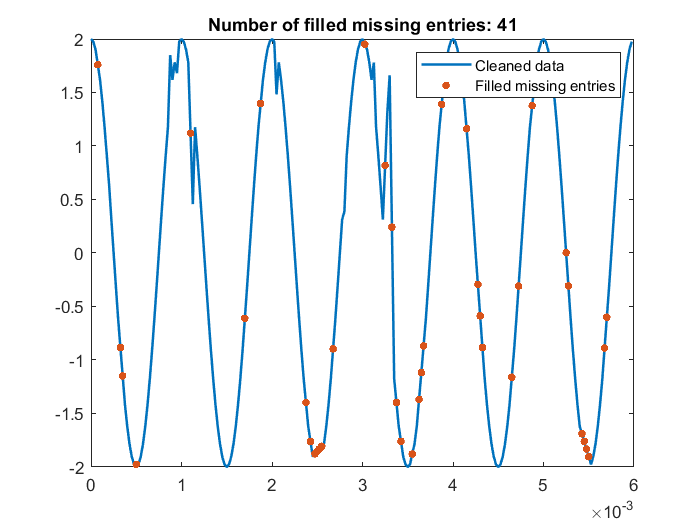

% Fill missing data
[Output,missingIndices] = fillmissing(s1,'linear','SamplePoints',t);

% Display results
clf
plot(t,Output,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Cleaned data')
hold on

% Plot filled missing entries
plot(t(missingIndices),Output(missingIndices),'.','MarkerSize',12,...
    'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])

hold off
legend

clear missingIndices

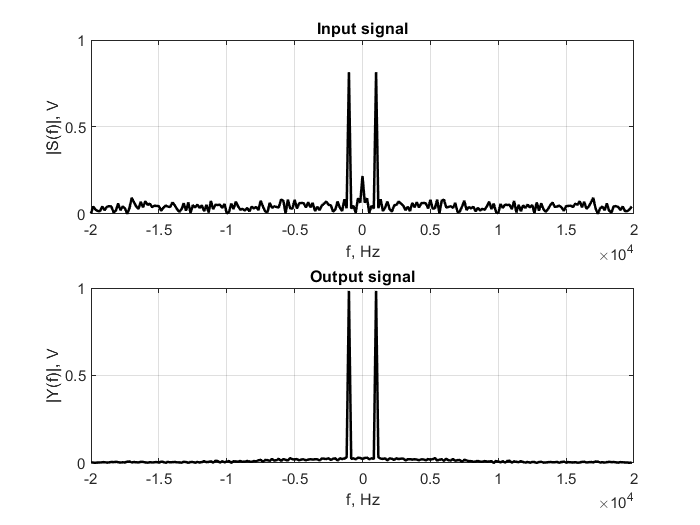

df = fs/N;
if mod(N,2)==1
    f = -(N-1)/2:(N+1)/2;
    f = f*df;
else
    f = -N/2:N/2-1;
    f = f*df;
end
S = fftshift(fft(s))/N;
FFTOutput = fftshift(fft(Output))/N;
subplot(2,1,1);
plot(f,abs(S),'-k','LineWidth',1.5); grid;
xlabel('f, Hz'); ylabel('|S(f)|, V');
title('Input signal'); ylim([0 1]);
subplot(2,1,2);
plot(f,abs(FFTOutput),'-k','LineWidth',1.5); grid;
xlabel('f, Hz'); ylabel('|Y(f)|, V');
title('Output signal'); ylim([0 1]);